load('C:\Users\Asus\Desktop\data_A')


x=data_noise(1:1000,1:11);
y=data_noise(1:1000,12);
rng('default');
cv = cvpartition(size(x,1),'HoldOut',0.3);
idx = cv.test;
% Separate to training and test data
x_train = x(~idx,:);
x_test  = x(idx,:);
y_train = y(~idx,:);
y_test  = y(idx,:);  

% absolute error
cvx_begin 
    variable teta_1(11,1);
    minimize(sum(abs(y_train-x_train*teta_1)));
cvx_end

 
Calling SDPT3 4.0: 1411 variables, 700 equality constraints
------------------------------------------------------------

 num. of constraints = 700
 dim. of socp   var  = 1400,   num. of socp blk  = 700
 dim. of free   var  = 11 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.9e-01|2.6e+01|1.8e+05| 5.684837e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.990|4.7e-09|3.6e-01|7.2e+03| 5.240571e+03  1.675906e-01| 0:0:00| chol  1  1 
 2|1.000|1.000|1.4e-08|9.8e-03|3.8e+02| 3.772199e+02  2.118064e-01| 0:0:00| chol  1  1 
 3|0.877|1.000|7.4e-07|9.8e-04|4.8e+01| 4.991508e+01  1.860121e+00| 

teta=teta_1

teta = 	1.0e+03 *

    0.0005
    0.0050
   -0.0271
    0.2277
   -0.8941
    1.8662
   -1.8152
   -0.0052
    1.6739
   -1.3904


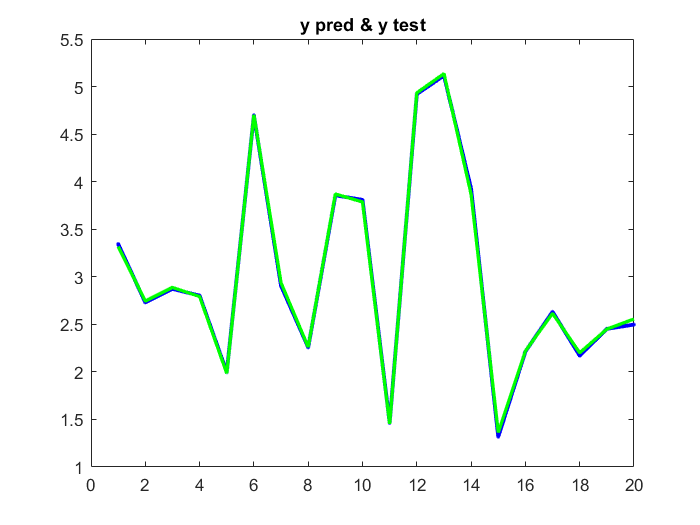

y_pred_train=x_train*teta;
   y_pred=x_test*teta;
   
   MSE = mean((y_pred - y_test).^2);
   MSE_test = MSE;
   
   MSE1 = mean((y_pred_train - y_train).^2);
   MSE_train = MSE1;
   
   errors =  y_test - y_pred;
   error_test=errors;
   
   errors1 =  y_train - y_pred_train;
   error_train=errors1;
   
   MAE = mean(abs(y_pred - y_test));
   MAE_test = MAE;

   MAE1 = mean((y_pred_train - y_train).^2);
   MAE_train = MAE1;
   
   
% subplot_rows = 3;
% subplot_cols = 4;
% 
%     % Generate the plot for the current i
% subplot(subplot_rows, subplot_cols, i);
u = x_test(:, 2);
cov_teta_hat = ((errors' * errors) * (x_train' * x_train)^-1)/(700-11);
errbar = sqrt(diag(x_test * cov_teta_hat * x_test'));






plot(y_pred(1:20,:),'.-b','linewidth',2.3);
hold on
plot(y_test(1:20,:),'-g','linewidth',2);
title("y pred & y test");
 hold off 

 
%  subplot(subplot_rows, subplot_cols, i);
% plot(y_pred,'.-b','linewidth',2.3);
% hold on
% plot(y_test,'-g','linewidth',2);
% title("y pred & y test");
%  hold off 
%  
 
 
 

ghodrat_noise=errors.'*errors/(700-11);
deghat_takhmin=cov(teta);
deghat_model=MSE;

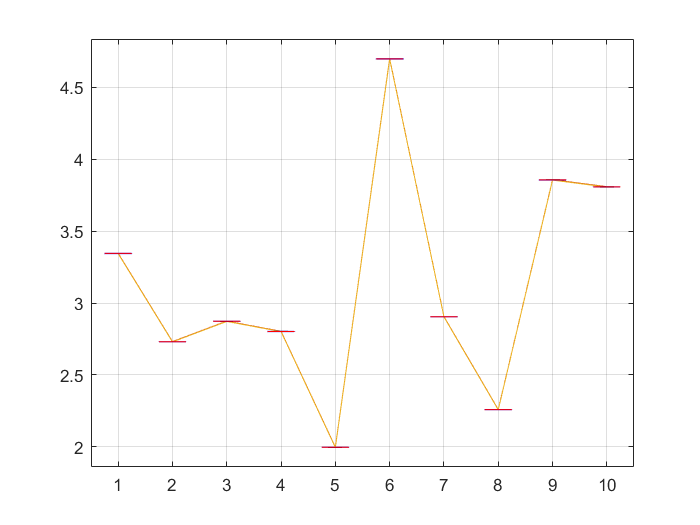

    
u1=1:1:10;
plot((y_pred(1:10,:)),'-');
hold on
plot((y_pred(1:10,:)+errbar(1:10,:)));
hold on
plot((y_pred(1:10,:)-errbar(1:10,:)));
grid

x=sort(u1).';
y=sort(y_pred(1:10,:)).';
data = [((y_pred(1:10,:))-errbar(1:10,:)).'; (y_pred(1:10,:)).'; ((y_pred(1:10,:))+errbar(1:10,:)).'];

% Add a box plot
boxplot(data, 'positions', x, 'widths', 0.5);
hold off

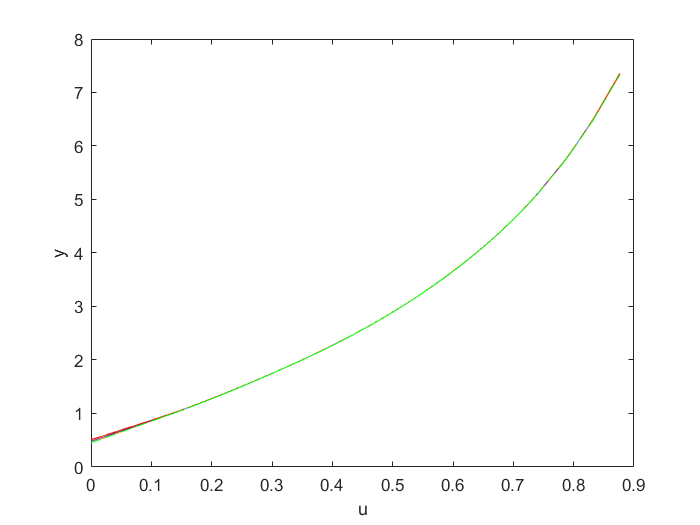

    upper_bound=y_pred + errbar;
    lower_bound=y_pred - errbar;
    
   [a_sorted, sort_idx] = sort(u);
b_sorted = y_pred(sort_idx);
c_sorted =upper_bound(sort_idx);
d_sorted =lower_bound(sort_idx);
% CI_low_sorted=CI_low(sort_idx)
% CI_high_sorted=CI_high(sort_idx)


plot(a_sorted, b_sorted, '-');
hold on;
plot(a_sorted, c_sorted, '-');
hold on
plot(a_sorted, d_sorted, '-');
hold on
% plot(a_sorted, CI_low_sorted, '-');
% hold on
% plot(a_sorted, CI_high_sorted, '-');
% hold on

for j = 1:length(a_sorted)-1
    x = [a_sorted(j), a_sorted(j+1)];
    y = [b_sorted(j), b_sorted(j+1)];
    plot(x, y);
    hold on
    xx = [a_sorted(j), a_sorted(j+1)];
    yy = [c_sorted(j), c_sorted(j+1)];
    plot(xx, yy, 'r--');
     hold on
    xxx = [a_sorted(j), a_sorted(j+1)];
    yyy = [d_sorted(j), d_sorted(j+1)];
    plot(xxx, yyy, 'g--');
%          hold on
%     xxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyy = [CI_low_sorted(j), CI_low_sorted(j+1)];
%     plot(xxxx, yyyy, 'g--');
%          hold on
%     xxxxx = [a_sorted(j), a_sorted(j+1)];
%     yyyyy = [CI_high_sorted(j), CI_high_sorted(j+1)];
%     plot(xxxxx, yyyyy, 'g--');
end
    xlabel('u');
    ylabel('y');


    % Set subplot title

    hold off

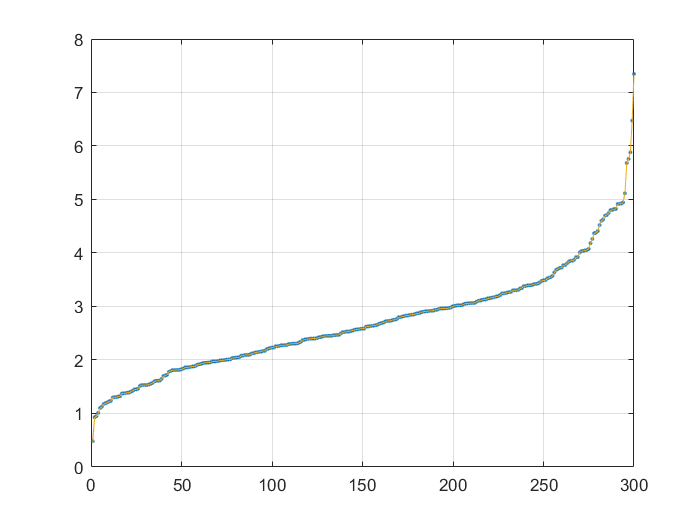

figure;
plot(sort(y_pred),'.');
hold on
plot(sort(y_pred+errbar));
hold on
plot(sort(y_pred-errbar));
grid

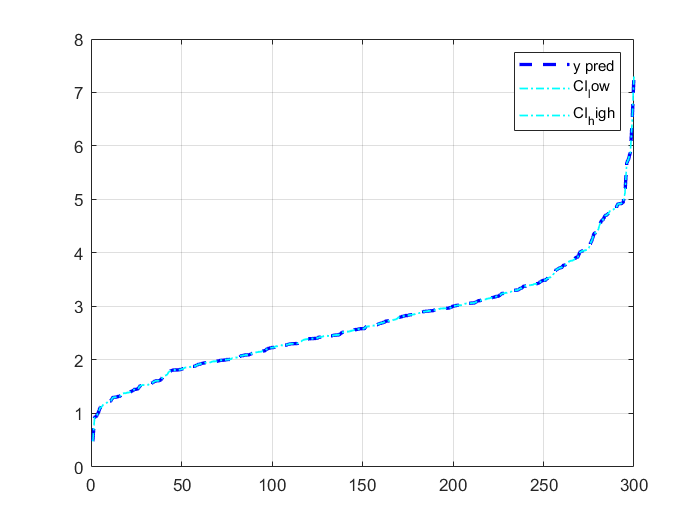

% Calculate the confidence interval
CI = 1.96 * std(errors) / sqrt(length(errors));
CI_low = y_pred - CI;
CI_high = y_pred + CI;

% Plot 
figure
plot(sort(y_pred), '--b', 'LineWidth', 2)
hold on
plot(sort(CI_low), '-.c', 'LineWidth', 1)
hold on
plot(sort(CI_high), '-.c', 'LineWidth', 1)
grid
legend('y pred', 'CI_low', 'CI_high')
hold off

disp('Ghodrat Noise');

Ghodrat Noise


disp(ghodrat_noise);

   2.6488e-04





disp('Deghat Takhmin');

Deghat Takhmin


disp(deghat_takhmin);

   1.2501e+06




disp('Deghat Model / Mean Square Error');

Deghat Model / Mean Square Error


disp(deghat_model);

   6.0834e-04

